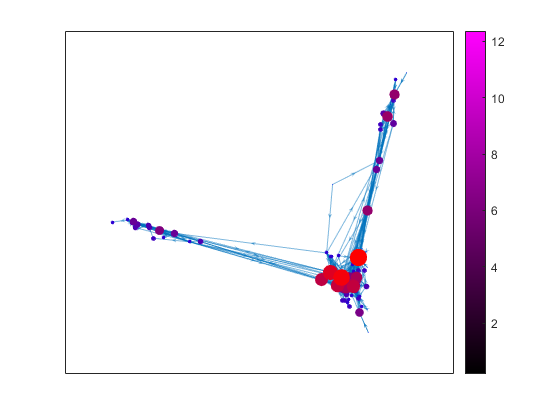

I=readtable("g_edges.csv");
S1=I.Source';
S1=string(S1);
T2=I.Target';
T2=string(T2);

G=digraph(S1,T2,(double(I.Weight))');
deg=indegree(G);
siz=2.*sqrt(deg-min(deg))+0.2;
color=[siz./max(siz)' zeros(length(siz),1) 1 - siz./max(siz)'];
plot(G,'MarkerSize',siz,'NodeColor',color);

caxis([min(siz),max(siz)]);
colormap([linspace(0,1,256);zeros(1,256);linspace(0,1,256)]');
colorbar;


top=sortrows([G.Nodes array2table(deg)],2,'descend');
disp(top(1:5,:));

       Name       deg
    __________    ___

    {'TYRION'}    37 
    {'NED'   }    34 
    {'ROBERT'}    28 
    {'SANSA' }    22 
    {'ROBB'  }    21 



disp(shortestpath(G,'NED','TYRION'));

    {'NED'}    {'PYP'}    {'TYRION'}

